# Practice Session Worksheet

## **Learning Outcomes**

By the end of this session, you’ll be able to:

- Use **Live Controls** and **Live Tasks** to make your lessons interactive.

- Leverage **MATLAB Copilot** to explain, comment, and debug code automatically.

- Explore ready-to-use **Simulink Virtual Labs** to enhance your curriculum.

## Exercise 1

Live Scripts make learning engaging and intuitive. They let students tweak parameters, run code, and visualize results instantly, all without writing or editing complex code. 

### 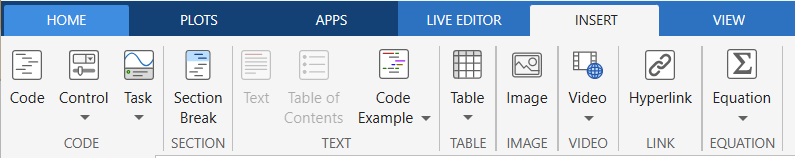

### Live Controls

Live Controls let students interactively adjust parameters and instantly see how changes affect results, making learning more engaging.

Activity 1 - Replace the variable "numRows" line of code below with a slider. Set the slider's default value to 1000, range = 500 to 1500, and step size = 100

*Tip:  You can run each code section by clicking the blue bar on the left or the "Run Section" button in the horizonal Taskbar.*

numRows = 1000;

### MATLAB Copilot

MATLAB Copilot can explain code and add comments. Below are a few lines of code with no comments. 

Activity 2 - Review the code below. Can you understand what this code does? What type of data is being plotted? What are the data's units? Ask Copilot to explain.

startTime = datetime('2023-01-01');
timeVector = startTime + minutes(1:numRows); 

T= 15 + 5 * rand(numRows, 1);
s = 30 + 5 * randn(numRows, 1);     
P = 1013 + 10 * rand(numRows, 1);  

seawater = timetable(timeVector', T, s, P,...
    'VariableNames', {'Temperature', 's', 'Pressure'});

figure
plot(seawater.Time, seawater.s)
hold on
plot(seawater.Time, seawater.Temperature)

*Tip: Select the lines of code you want explained. Click on Copilot in the Live Editor tab and select "Explain Code"*

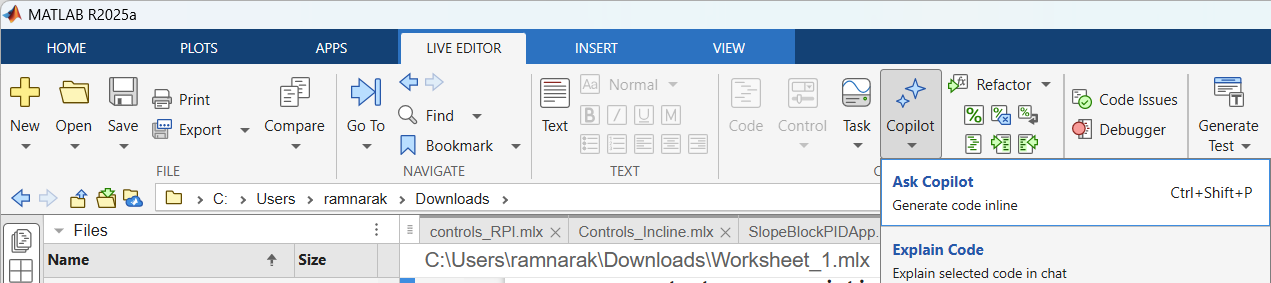

Now that we understand what the code accomplishes, how do we communicate this to anyone reading the script? -- Comments!

Activity 3 - Ask Copilot to add comments to clarify what each line of code does. Update the code above with comments so that readers of the script can understand what's happening.

% Enter code here  (WHAT IS THIS FOR??? Were they supposed to copy the
% code?)

*(Tip: Look for "Generate Comments" in the Copilot dropdown)*

## Exercise 2

### Live Tasks

Live Tasks enable students to learn core concepts via point-and-click tools instead of just code. 

Activity 4 - Insert the Live task that allows you to *retime* timetable data. Pick one of the variables, such as "seawater" from the data above and adjust the timing between each sample point.

% Insert a live task

*(Tip: Under the "Insert" tab, look through the "Task" drop down)*

*Experiment with different rules. Also, you can click on the ellipsis near the Live Task heading to convert it to code!*

### Enhancing your Plots

You can ask MATLAB Copilot for suggestions on how to enhance your code and figures

Activity 5

Plot your retimed data on a new figure by inserting the code in the code box below.

Ask Copilot what lines of code you can add to help clarify a plot, such as increasing font size, adding labels, and changing the colors.  

% insert a figure
figure


*Bonus - Open the figure editor window and interactively add or modify properties of the figure, such as Title, Axes Labels, Marker Size. *

*Tip: Use the Figure tab → Show Code to copy your figure edits back into your script.*

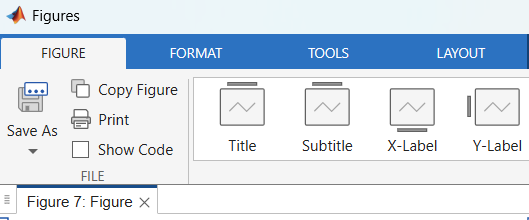

## Exercise 3

### Simulink Virtual Labs

1. Navigate to [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/) and search on "virtual labs". Find the "DC Circuit Analysis Lab" and click   .

2. Double click on the ".prj" file. 

3. Find a Simulink model within the project called "Virtual Oscilloscope.slx" (It may be stored in subfolders. Look for a ".slx" file extension). 

An oscilloscope is a type of electronic test instrument that graphically displays varying voltages of different signals. We don't have a physical oscilloscope here today, but we have a *virtual* one.

4. Double Click the .slx file. This should launch Simulink and bring up the oscilloscope model**, which is conspicuously lacking a ciruit to monitor. **

You can use premade virtual Simulink labs to help your students put theory into practice without having to start from scratch and sometimes without even needing physical hardware!

*Reflection: How can you use a virtual lab to teach a difficult concept in your course?*

## **Further Exploration**

1) Check out another virtual lab! [Virtual Hardware for Labs and Control](https://www.mathworks.com/matlabcentral/fileexchange/100064-virtual-hardware-and-labs-for-controls) may supplement your current course curriculum.

2) MATLAB Copilot can generate test cases for your code, finding uncovered edge cases and other coding erros. This feature enables students to double-check their work before submitting.

3) Ask Copilot to explain any errors you run into. You can see the "Explain Error" option in the Copilot Chat panel to the right.

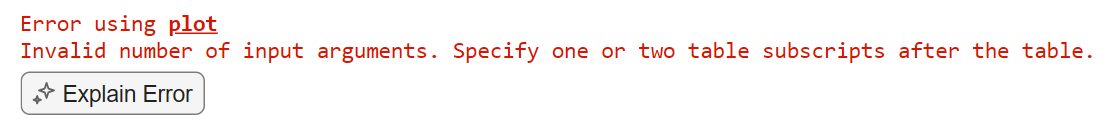

4) Explore other Live Tasks for pre-processing data and common mathematical operations.